# Ricerca di radici di equazioni non lineari

## Introduzione

Cercare e trovare una possibile **radice di un'equazione** non lineare in MATLAB significa trovare un valore per cui la funzione valutata in quel punto, sia **zero**. Per essere più precisi, chiamiamo $x\in \mathbb{R}$ la variabile data in pasto alla funzione $f:\mathbb{R}\to \mathbb{R}$. Quando $f\left(x\right)=0$ il valore di $x$ porta a valutare la funzione a zero: in un grafico, la curva della funzione attraverserà l'asse delle ascisse nell'esatto punto.

Prendiamo la funzione $\sin$ come esempio e valutiamola nell'intervallo $\left\lbrack 0,2\pi \right\rbrack$. La curva è periodica e attraversa l'asse zero delle ascisse nei multipli di $\pi$. Stampiamo la funzione e il punto dove la curva interseca l'asse.

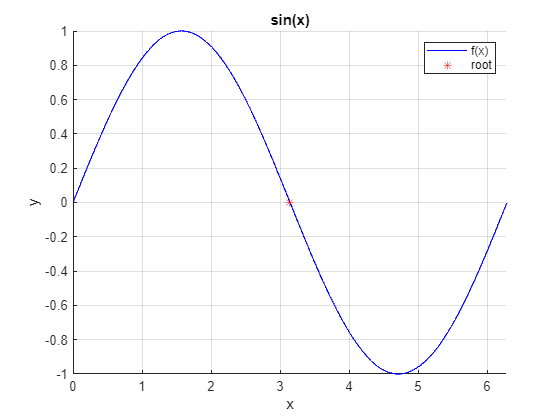

f = @(x) sin(x); % funzione periodica
x = linspace(0, 2*pi, 1000);
r = pi;

figure; hold on; grid on
xlabel('x'); ylabel('y'); xlim([min(x) max(x)])
title('sin(x)')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')
plot(r, f(r), 'r*', 'DisplayName', 'root')
legend

## Algoritmi

Gli algoritmi di ricerca permettono di trovare, anche se spesso in forma non esatta (ma con alta precisione), una o più radici di equazione. Sapere a priori quale è la radice esatta di una funzione come $\sin$ sconfigge il proposito di quesi algoritmi, quindi vediamo altri esempi e i metodi di ricerca uno a uno con vantaggi/svantaggi.

### Metodo di bisezione

Il metodo di bisezione si affida alla **divisione dell'intervallo interessato nella ricerca**, **a metà**, a ogni iterazione. Questo riduce le possibilità di radice a una sola o comunque a una soluzione precisa al punto tale da poter soddisfarci. La formula


$$x=\left(a+b\right)*0\ldotp 5$$


indica il punto medio e bisezione dell'intervallo. Dato un'intervallo $\left\lbrack a,b\right\rbrack$ entro cui la funzione viene valutata, possiamo sapere a priori se in quell'intervallo esisterà una radice usando il **teorema di esistenza degli zeri** il quale afferma che esiste una radice nell'intervallo, se la moltiplicazione dei valori della funzione valutata agli estremi risulta minore di zero


$$\exists x\in \left\lbrack a,b\right\rbrack :f\left(a\right)f\left(b\right)<0$$


Questo funziona perché a sinistra/destra della radice, la funzione avrà valore positivo/negativo, mentre nel punto esatto sarà zero. Usando questo metodo, a ogni iterazione, siamo assicurati convergere a una radice.

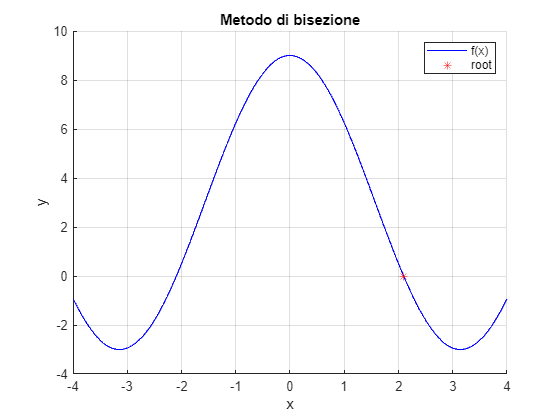

f = @(x) 3 + 6*cos(x); % funzione periodica
x = linspace(-4,4,1000); % intervallo di funzione

figure; hold on; grid on
xlabel('x'); ylabel('y'); xlim([min(x) max(x)])
title('Metodo di bisezione')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')
legend

a = 1; b = 3; % intervallo di ricerca

[v, y, iter] = bisection(f, a, b, 10^-10, 100);
r = v(iter);

plot(r, f(r), 'r*', 'DisplayName', 'root')


sprintf('Found root: %.16f\nNumber of iterations: %d', v(iter), iter)

ans =     'Found root: 2.0943951023800764
     Number of iterations: 36'


#### Vantaggi

Quando un metodo di bisezione si dice **convergere a una soluzione**, significa che questo metodo raggiunge una soluzione in un certo tempo. Il metodo di bisezione è da dirsi **globalmente convergente** perché assicura la convergenza verso una radice possibile dell'equazione. La radice $x$ al passo $m$ per $m\to \infty$, cercata nell'intervallo $I$, avrà pressoché errore nullo $e_{\left(m\right)}$ rispetto la radice esatta $\alpha$, nei limiti dello zero in rappresentazione macchina.


$$e_{\left(m\right)} =|x_{\left(m\right)} -\alpha |\le |I_{\left(m\right)} |=|b_{\left(m\right)} -a_{\left(m\right)} |=\frac{|I_0 |}{2^m }$$


#### Svantaggi

Il metodo ricerca con un ritmo che **non è monotono in errore**. Questo succede perché la bisezione avvicina sì verso la radice ma lo fa per cui l'errore al passo $k+1$ dell'algoritmo può essere maggiore dell'errore commesso al passo $k$.

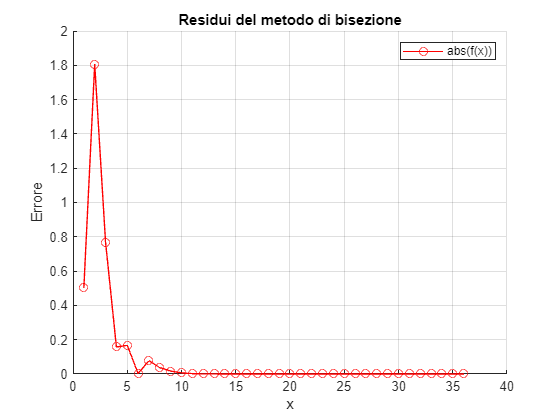

figure; hold on; grid on;
xlabel('x'); ylabel('Errore')
title('Residui del metodo di bisezione')
plot(y, 'r-o', 'DisplayName', 'abs(f(x))')
legend

Una successione di approssimanti della radice **converge con ordine **$p$ se


$$\exists c>0:\frac{|x_{\left(k+1\right)} -\alpha |}{|x_{\left(k\right)} -\alpha |^p }\le c\;\;\;\;\;\;\;\;\forall k\ge k_0 \;\;\;\;\;\;\;\;k_0 \in \mathbb{N}$$


L'algoritmo di bisezione **non ha nemmeno ordine di convergenza a 1**.

### Metodo delle secanti

Il metodo delle secanti approssima la radice usando una costruzione di **rette passanti per due punti**. La formula che approssima la radice $x_{k+1}$ è data dalla radice al passo precedente $x_k$


$$x_{k+1} =x_k -\frac{b-a}{f\left(b\right)-f\left(a\right)}f\left(x_k \right)\;\;\;\;\;\;\;\;k=0,1,\ldotp \ldotp$$


Uno dei punti attraverso cui le rette passano sarà sull'asse delle ascisse ed è la radice approssimata.

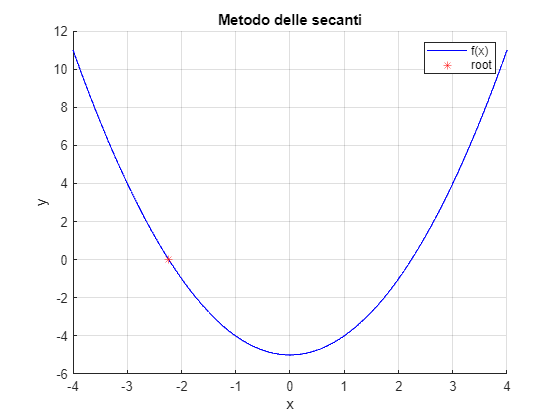

f = @(x) x.^2 - 5; % exp(x) + x;
x = linspace(-4,4,1000); % intervallo di funzione

figure; hold on; grid on
xlabel('x'); ylabel('y'); xlim([min(x) max(x)])
title('Metodo delle secanti')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')
legend

a = -3; b = -1; % [-3 -1], [-3 1]

[v, ~, iter] = secant(f, a, b, 10^-10, 100);
r = v(iter);

plot(r, f(r), 'r*', 'DisplayName', 'root')


sprintf('Found root: %.16f\nNumber of iterations: %d', v(iter), iter)

ans =     'Found root: -2.2360679774997898
     Number of iterations: 21'


#### Vantaggi

Il metodo delle secanti ha **ordine di convergenza 1**, nettamente migliore rispetto al metodo di bisezione. La velocità di convergenza è maggiore.

#### Svantaggi

Molti dei metodi di convergenza non è globalmente convergente. Quello che si tende fare durante la ricerca di una radice è utilizzare un metodo che sia assicurato convergere verso una radice per poi passare a uno più veloce, una volta stabiliti i limiti di ricerca. Il metodo delle secanti, come tanti altri, si dice essere **localmente convergente** perché non assicura la convergenza verso radice, a seconda degli intervalli selezionati. Inoltre non è detto converga raggiungendo la tolleranza prestabilita prima di raggiungere il numero di iterazioni massime specificate.

### Metodo di Newton

Il metodo di Newton, anche detto metodo delle tangenti, si basa sulla costruzione di **rette passanti** per il punto approssimato $x_{k+1}$ usando come punto d'innesco $x_k$ e la formula


$$x_{k+1} =x_k -\frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}\;\;\;\;\;\;\;\;k=0,1,\ldotp \ldotp$$


L'uso della derivata serve come sorta di gradiente della funzione: per definizione serve a quantificare il cambiamento di una funzione al variare dell'input. In congiunzione con la valutazione della funzione, la derivata serve proprio per capire quale $x$ al passo $k$, approssimi senza grandi variazioni, la radice.

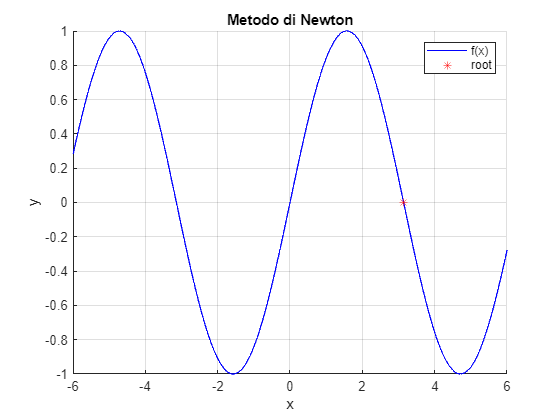

f = @(x) sin(x);
df = @(x) cos(x); % derivata
x = linspace(-6,6,1000); % intervallo di funzione

figure; hold on; grid on
xlabel('x'); ylabel('y'); xlim([min(x) max(x)])
title('Metodo di Newton')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')
legend

x0 = 4;

[v, ~, iter] = newton(f, df, x0, 10^-10, 100);
r = v(iter);

plot(r, f(r), 'r*', 'DisplayName', 'root')


sprintf('Found root: %.16f\nNumber of iterations: %d', v(iter), iter)

ans =     'Found root: 3.1415926535897931
     Number of iterations: 4'


#### Vantaggi

Questo metodo è molto veloce nel convergere a possibile radice: l'**ordine di convergenza è pari a 2**.

#### Svantaggi

Come molti, questo metodo è **localmente convergente** il che significa che converge a radice solamente sotto date condizioni. Il metodo di Newton non assicura la convergenza per funzioni come $f\left(x\right)=x^2$, continua derivabile che però vale $f^{\prime } \left(x\right)=0$ alla radice; la funzione $f\left(x\right)=x+\frac{4}{3}x$ ha derivata non nulla alla radice ma nessuna derivata seconda: la convergenza non è assicurata.

## Criteri di arresto

Gli algoritmi di ricerca hanno criteri che impongono stop all'algoritmo in caso un'approssimazione precisa abbastanza della radice venga trovata o il superamento di una certa soglia sia soddisfatto. I criteri di arresto di cui facciamo uso sono

- **criterio del residuo**, per cui un algoritmo si arresta al minimo valore di $k$ tale che $|f\left(x_k \right)|<\varepsilon$

- **criterio dell'incremento**, per cui l'algoritmo si arresta al minimo valore $k$ tale che $|x_{\left(k+1\right)} -x_{\left(k\right)} |<\varepsilon$

Questi due criteri, in aggiunta al **numero massimo di iterazioni** permesse, sono un ottimo modo per bloccare l'esecuzione ed evitare il consumo di memoria.

## Comandi di ricerca in MATLAB

In MATLAB due **comandi** sono stati visti **per ottenere le radici di equazioni non lineari**.

- `roots(C)` calcola le **radici di una equazione polinomiale** usando i coefficienti definiti in `C`.

- `fzero(FUN,X0)` **cerca una radice della funzione** definita come function handle `FUN` usando come punto d'innesco lo scalare `X0` oppure un vettore di lunghezza 2.

L'ultima delle due applica dietro le quinte gli algoritmi visti sopra e lo fa in modo intelligente a seconda di dinamiche che non andiamo a vedere. Quello che importa è che il risultato di questo comando può essere usato come controllo nel test di precisione dei nostri metodi.

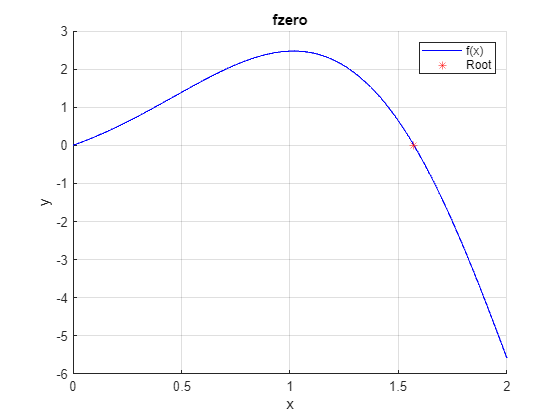

f = @(x) exp(x) .* sin(2*x);
df = @(x) 2*exp(x)*cos(2*x) + exp(x)*log(exp(1))*sin(2*x); % per metodo di Newton

a = 2; b = "1"; % intervallo ricerca
x0 = 2; % punto innesco

x = linspace(0, 2, 1000); % intervallo funzione

figure; hold on; grid on
xlabel('x'); ylabel('y')
title('fzero')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')

r0 = fzero(f, x0);

plot(r0, f(r0), 'r*', 'DisplayName', 'Root')
legend


[v, ~, iter] = newton(f, df, x0, 10^-8, 100);
sprintf('Exact root: %.16f\nMy root: %.16f', r0, v(iter))

ans =     'Exact root: 1.5707963267948966
     My root: 1.5707963269251377'


L'errore lo calcoliamo in valore assoluto rispetto la radice esatta

err = abs(r0 - v(iter))

err = 1.3024e-10